# DL-SCH and PDSCH Transmit and Receive Processing Chain

This is a tutorial on the patterns we use in the 5G Toolbox to model a PDSCH link, including all steps from transport block generation to DL-SCH decoding.

This example implements a PDSCH link where a single slot is transmitted. The example shows how to implement the following steps:

- DL-SCH encoding (without HARQ)

- PDSCH encoding

- Precoding

- OFDM modulation

- Propagation channel and noise addition

- Timing synchronization

- OFDM demodulation

- Channel estimation

- PDSCH decoding

- DL-SCH decoding

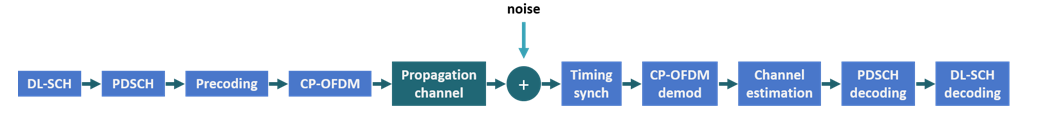

## Simulation Parameters

Specify the desired SNR and the perfect channel estimation flag.

SNRdB = 15;                 % SNR in dB
perfectEstimation = false;  % perfect synchronisation and channel estimation
offset = 0;                 % initialize offset

## Carrier Configuration

Set up a carrier configuration object. Here you can set up the numerology. We will use the default parameters.

carrier = nrCarrierConfig

carrier =   nrCarrierConfig with properties:

              NCellID: 1
    SubcarrierSpacing: 15
         CyclicPrefix: 'normal'
            NSizeGrid: 52
           NStartGrid: 0
                NSlot: 0
               NFrame: 0

   Read-only properties:
       SymbolsPerSlot: 14
     SlotsPerSubframe: 1
        SlotsPerFrame: 10


Set the desired slot number.

carrier.NSlot = 0;

## PDSCH and DM-RS Configuration

Set up a PDSCH configuration object. Specify 16QAM modulation, 2 layers and full band allocation. Other time allocation parameters and DM-RS settings can be specified in this object.

pdsch = nrPDSCHConfig;
pdsch.Modulation = "16QAM";
pdsch.NumLayers = 2;
pdsch.PRBSet = 0:carrier.NSizeGrid-1;     % full band allocation

Display the PDSCH parameters.

pdsch

pdsch =   nrPDSCHConfig with properties:

                NSizeBWP: []
               NStartBWP: []
             ReservedPRB: {[1×1 nrPDSCHReservedConfig]}
              ReservedRE: []
              Modulation: '16QAM'
               NumLayers: 2
             MappingType: 'A'
        SymbolAllocation: [0 14]
                  PRBSet: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
    VRBToPRBInterleaving: 0
           VRBBundleSize: 2
                     NID: []
                    RNTI: 1
                    DMRS: [1×1 nrPDSCHDMRSConfig]
              EnablePTRS: 0
                    PTRS: [1×1 nrPDSCHPTRSConfig]

   Read-only properties:
            NumCodewords: 1


Set the DM-RS parameters. Add an additional DM-RS position to improve channel estimation

pdsch.DMRS.DMRSAdditionalPosition = 1; 

Set the DM-RS configuration type and the DM-RS length to support the specified number of layers:

- `DMRSConfigurationType = 1`: You can use up to 4 layers for `DMRSLength = 1`.

- `DMRSConfigurationType = 1`: You can use up to 8 layers for `DMRSLength = 2`.

- `DMRSConfigurationType = 2`: You can use up to 6 layers for `DMRSLength = 1`.

- `DMRSConfigurationType = 2`: You can use up to 12 layers for `DMRSLength = 2`.

pdsch.DMRS.DMRSConfigurationType = 1;
pdsch.DMRS.DMRSLength = 2;
pdsch.DMRS % display parameters

ans =   nrPDSCHDMRSConfig with properties:

      DMRSConfigurationType: 1
         DMRSReferencePoint: 'CRB0'
          DMRSTypeAPosition: 2
     DMRSAdditionalPosition: 1
                 DMRSLength: 2
            CustomSymbolSet: []
                DMRSPortSet: []
                   NIDNSCID: []
                      NSCID: 0
    NumCDMGroupsWithoutData: 2

   Read-only properties:
                  CDMGroups: [0 0]
                DeltaShifts: [0 0]
           FrequencyWeights: [2×2 double]
                TimeWeights: [2×2 double]
    DMRSSubcarrierLocations: [6×2 double]
                 CDMLengths: [2 1]


## DL-SCH Configuration

Specify the coding rate and the redundancy version value. In this example we do not consider HARQ, therefore the redundancy value (RV) is fixed during the simulation.

% Coding rate and redundancy version
if pdsch.NumCodewords == 1
    codeRate = 490/1024;
    RV = 0; % redundancy value
else
    codeRate = [490 490]./1024;
    RV = [0 0]; % redundancy value
end

Create the DL-SCH encoder and decoder objects.

% Create DL-SCH encoder object
encodeDLSCH = nrDLSCH;
encodeDLSCH.TargetCodeRate = codeRate;

% Create DLSCH decoder object
decodeDLSCH = nrDLSCHDecoder;
decodeDLSCH.TargetCodeRate = codeRate;
decodeDLSCH.LDPCDecodingAlgorithm = "Normalized min-sum";
decodeDLSCH.MaximumLDPCIterationCount = 6;

## Channel Configuration

Specify the number of transmit and receive antennas

nTxAnts = 8;
nRxAnts = 8;
% Check the number of layers is valid for the number of antennas
if pdsch.NumLayers > min(nTxAnts,nRxAnts)
    error("The number of layers ("+string(pdsch.NumLayers)+") must be smaller than min(nTxAnts,nRxAnts) ("+string(min(nTxAnts,nRxAnts))+")")
end

% Create the channel object
channel = nrTDLChannel; % TDL channel object
channel.DelayProfile = 'TDL-A';
%channel.DelaySpread = 3.0000e-10;
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;

Set the channel sampling rate. Use the same value as the OFDM signal.

ofdmInfo = nrOFDMInfo(carrier);
channel.SampleRate = ofdmInfo.SampleRate;

## Calculate Transport Block Size

Use the function `nrTBS` to calculate the transport block size.

% Generate PDSCH indices info, this is used to calculate the transport
% block size
[pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch);

% Calculate transport block sizes
Xoh_PDSCH = 0;
trBlkSizes = nrTBS(pdsch.Modulation,pdsch.NumLayers,numel(pdsch.PRBSet),pdschInfo.NREPerPRB,codeRate,Xoh_PDSCH);

## DL-SCH Encoding

Generate the transport blocks. You need one transport block per codeword.

% Generate new transport block
for cwIdx = 1:pdsch.NumCodewords
    trBlk = randi([0 1],trBlkSizes(cwIdx),1);
    setTransportBlock(encodeDLSCH,trBlk,cwIdx-1);
end

Encode the DL-SCH transport blocks

codedTrBlock = encodeDLSCH(pdsch.Modulation,pdsch.NumLayers,pdschInfo.G,RV);

## PDSCH Modulation and Precoding

Generate PDSCH symbols from the coded transport blocks.

pdschSymbols = nrPDSCH(carrier,pdsch,codedTrBlock);

Get the precoding weights. In this example we assume knowledge of the channel. The NR PDSCH Throughput example (***link here***) uses the channel estimate at the receiver to calculate the weights used for the tranmsission in the next slot. For the first slot to transmit, we perform a perfect channel estimation to calculate the weights for that first slot.

estChannelGrid = getInitialChannelEstimate(channel,carrier);
precodingWeights = getPrecodingMatrix(pdsch.PRBSet,pdsch.NumLayers,estChannelGrid);

Precode the PDSCH symbols.

pdschSymbolsPrecoded = pdschSymbols*precodingWeights;

## PDSCH DM-RS Generation

Generate DM-RS symbols and indices.

dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);

## Mapping to Resource Grid

Generate an empty resource grid. This grid represents a slot.

pdschGrid = nrResourceGrid(carrier,nTxAnts);

Map the PDSCH symbols to the grid and display the resource grid (first antenna). Note that the PDSCH indices obtained refer to layers, not antennas. 

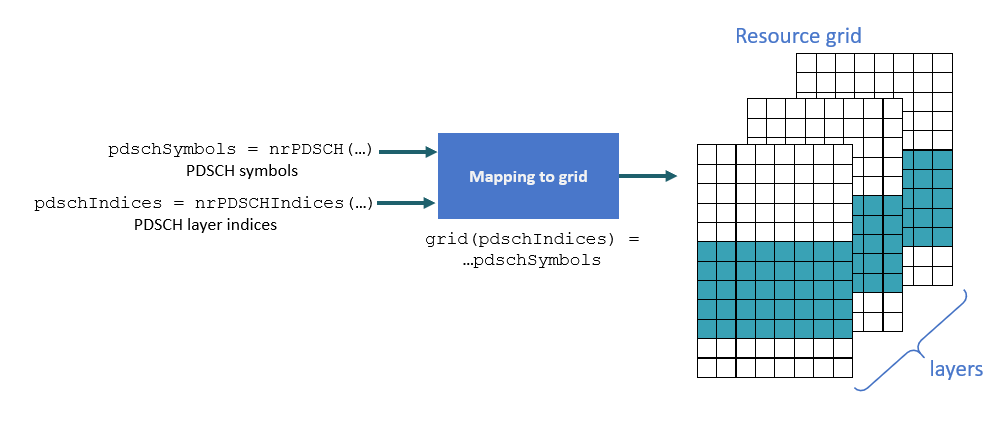

In this example we need to map precoded PDSCH symbols. This means these symbols map to antennas, not layers. The function nrExtractResources() converts layer indices to antenna indices.

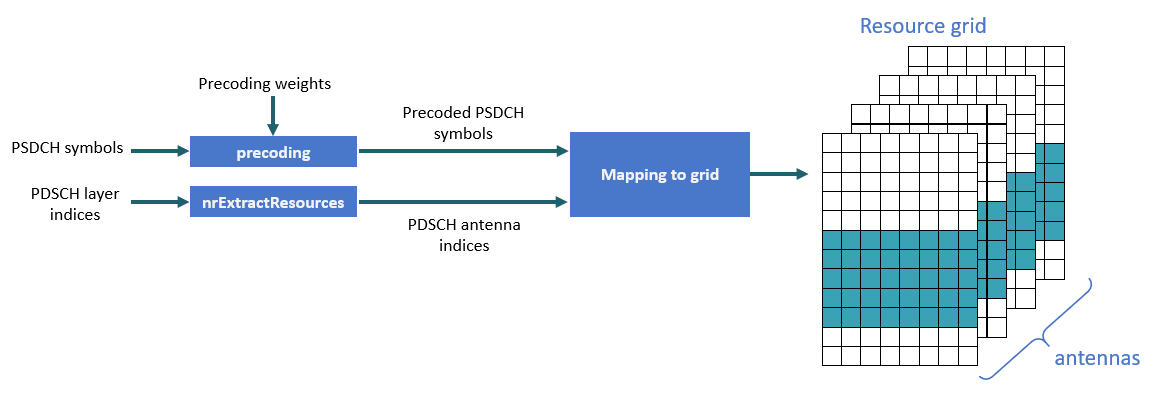

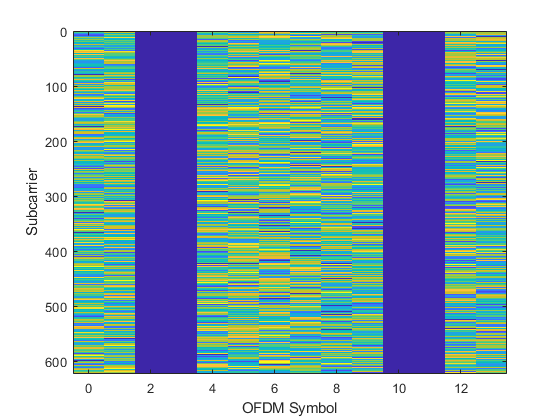

[~,pdschAntIndices] = nrExtractResources(pdschIndices,pdschGrid);
pdschGrid(pdschAntIndices) = pdschSymbolsPrecoded;
figure;
imagesc([0 carrier.SymbolsPerSlot-1],[0 carrier.NSizeGrid*12-1],abs(pdschGrid(:,:,1)));
xlabel('OFDM Symbol');
ylabel('Subcarrier');

Precode DM-RS symbols and map to grid. Similarly to the PDSCH, the DM-RS indices are calculated for the specified number of layers, the function nrExtractResources() is used again to convert these to multiantenna indices.

% PDSCH DM-RS precoding and mapping
for p = 1:size(dmrsSymbols,2)
    [~,dmrsAntIndices] = nrExtractResources(dmrsIndices(:,p),pdschGrid);
    pdschGrid(dmrsAntIndices) = pdschGrid(dmrsAntIndices) + dmrsSymbols(:,p)*precodingWeights(p,:);
end

Display the grid for the first antenna.

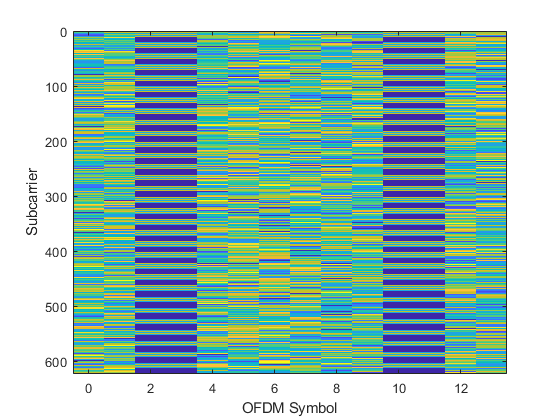

imagesc([0 carrier.SymbolsPerSlot-1],[0 carrier.NSizeGrid*12-1],abs(pdschGrid(:,:,1)));
xlabel('OFDM Symbol');
ylabel('Subcarrier');

## OFDM Modulation

Perform OFDM modulation of the resource grid.

[txWaveform,waveformInfo] = nrOFDMModulate(carrier,pdschGrid);

Plot the time domain waveform magnitude.

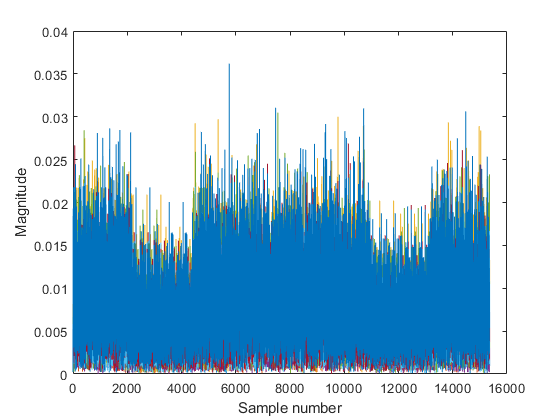

figure;
plot(abs(txWaveform));
xlabel('Sample number');
ylabel('Magnitude');

## Propagation Channel

The propagation channel generates N output samples given an input with N samples. However, the block of N output samples includes the filter transient. This means that part of the input samples are inside the channel filter delay line and have not been filtered yet. To flush all relevant samples out of the channel filter, we pad the input signal with zeros. The amount of padding is determined by the maximum delay introduced by the channel filter. This includes the delay introduced by all multipath components and the channel filter implementation delay.

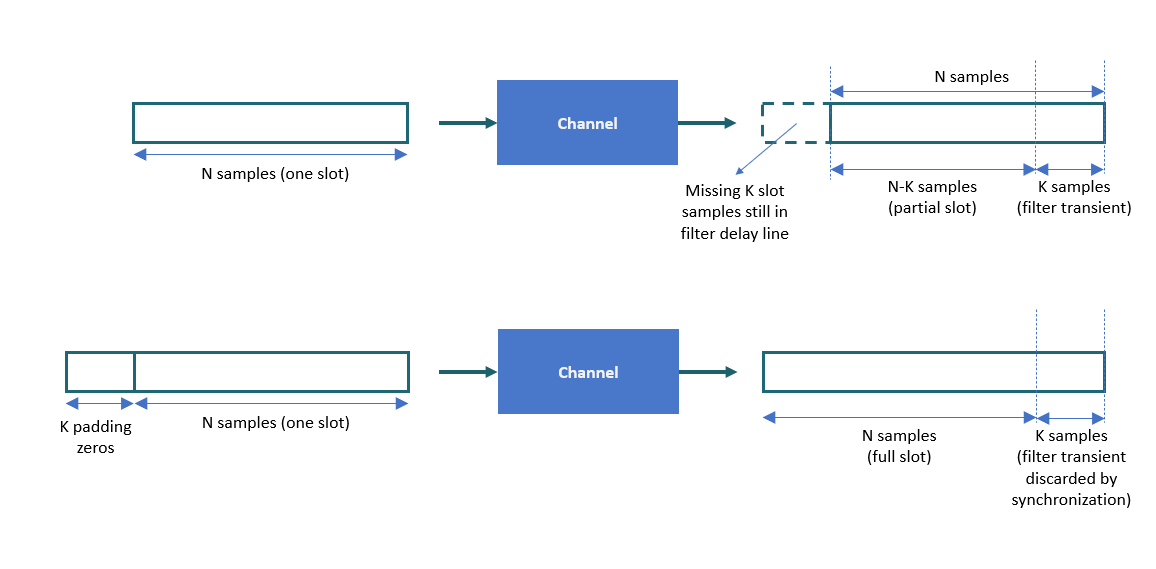

Pad the input signal with enough zeros to ensure the generated signal is flushed out of the filter.  

chInfo = info(channel);
maxChDelay = ceil(max(chInfo.PathDelays*channel.SampleRate)) + chInfo.ChannelFilterDelay;
txWaveform = [txWaveform; zeros(maxChDelay, size(txWaveform,2))];

Send signal through the channel and add noise.

[rxWaveform,pathGains,sampleTimes] = channel(txWaveform);
noise = generateAWGN(SNRdB,nRxAnts,waveformInfo.Nfft,size(rxWaveform));
rxWaveform = rxWaveform + noise;

## Timing Synchronization

You can perform perfect or practical synchronization:

- Perfect synchronization is based on channel knowledge. We use the path gains and path filters impulse response information provided by the channel. This allows us to work out the offset associated to the strongest multipath component across all channel snapshots and across all transmit and receive antennas.

- Practical synchronization performs a cross correlation of the received signal with the DM-RS symbols in the time domain. In some adverse cases, due to fading or noise, this cross correlation can be weak, resulting in an erroneous timing offset. The function `hSkipWeakTimingOffset `checks the magnitude of the cross correlation `mag`. If it is weak, the current timing estimate `t` is ignored, and the previous estimate `offset` is used.

if perfectEstimation
    pathFilters = getPathFilters(channel); % get path filters for perfect channel estimation
    [offset,mag] = nrPerfectTimingEstimate(pathGains,pathFilters);
else
    [t,mag] = nrTimingEstimate(carrier,rxWaveform,dmrsIndices,dmrsSymbols);
    offset = hSkipWeakTimingOffset(offset,t,mag);
end
rxWaveform = rxWaveform(1+offset:end, :);

## OFDM Demodulation

rxGrid = nrOFDMDemodulate(carrier,rxWaveform);

## Channel Estimation

You can perform perfect or practical channel estimation:

- Perfect channel estimation is based on channel knowledge. This provides an estimate of channel conditions between transmit and receive antennas. However, the channel estimate required is between the transmit layers and the receive antennas. Therefore, we must precode the channel estimate as shown below.

- Practical channel estimation is based on DM-RS assisted channel estimation with noise averaging and interpolation to obtain an estimate for all resource elements in the slot. Since the DM-RSs are specified per layer, the resulting channel estimate represents the channel conditions between the transmit layers and the receive antennas. Therefore, it already includes the effect of the precoding operation.

if perfectEstimation
    % Perfect channel estimation between all transmit and all receive
    % antennas
    estChGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);
    
    % Get perfect noise estimate (from the noise realization)
    noiseGrid = nrOFDMDemodulate(carrier,noise(1+offset:end ,:));
    noiseEst = var(noiseGrid(:));
    
    % Apply precoding to estChannelGrid. The resulting estimate is for the
    % channel between layers and receive antennas
    estChGrid = precodeChannelEstimate(estChGrid,precodingWeights.');
else
    [estChGrid,noiseEst] = nrChannelEstimate(carrier,rxGrid,dmrsIndices,dmrsSymbols,'CDMLengths',pdsch.DMRS.CDMLengths);
end

Plot the channel estimate between the first layer and the first receive antenna.

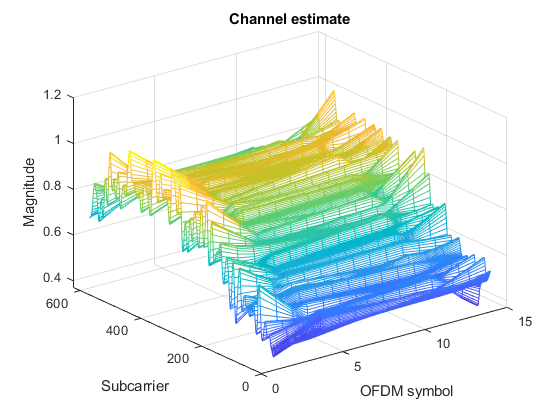

figure; mesh(abs(estChGrid(:,:,1,1)));
title('Channel estimate')
xlabel('OFDM symbol');
ylabel("Subcarrier");
zlabel("Magnitude")

At this point, the channel estimate can be used to obtain the precoding matrix for transmission in the next slot. This example only transmits one slot, therefore we do not need to calculate the precoding matrix. The NR PDSCH Throughput example  models the transmission of several slots, and at this point of the code, it includes the calculation of beamforming weights.

## Equalization

Extract the PDSCH symbols from the received grid and the associated channel estimates. The `csi` output has channel state information for each of the equalized PDSCH symbols.

[pdschRx,pdschHest] = nrExtractResources(pdschIndices,rxGrid,estChGrid);
[pdschEq,csi] = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);

Plot the constellation of the equalized symbols. Create a constellation diagram and enable measurements to check the EVM. You need to specify the reference constellation points to measure the EVM.

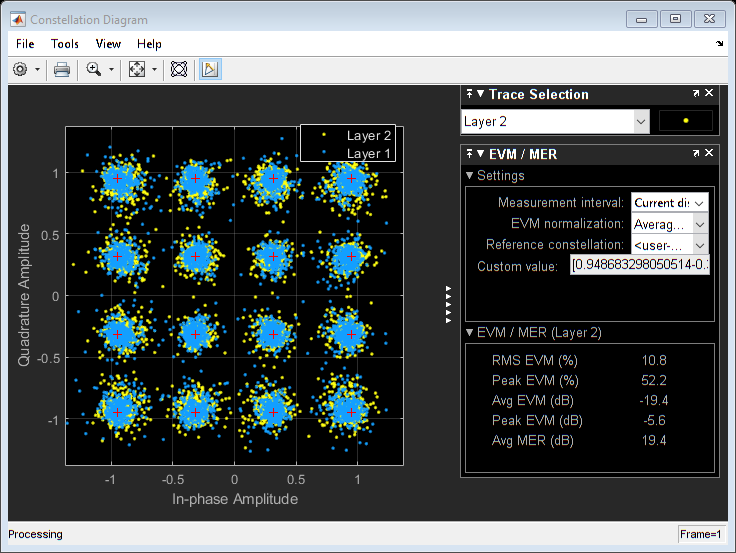

constPlot = comm.ConstellationDiagram;
constPlot.EnableMeasurements = 1;
constPlot.ReferenceConstellation = mat2cell(pdschSymbols,size(pdschSymbols,1),ones(1,size(pdschSymbols,2)));
% Constellation for the first layer has a higher SNR than the constellation
% for the last layer. Flip the layers so the constellations don't mask each
% other
pdschConst = fliplr(pdschEq); 
for n=pdsch.NumLayers:-1:1
    idx = pdsch.NumLayers-n+1;
    constLegend{idx} = ['Layer ' num2str(n)];
end
constPlot.ChannelNames = constLegend;
constPlot.ShowLegend = true;
constPlot(pdschConst);

## PDSCH Decoding

[dlschLLRs,rxSymbols] = nrPDSCHDecode(carrier,pdsch,pdschEq,noiseEst);

Scale LLRs by CSI. This applies a larger weight to the symbols for resource elements with better channel conditions.

% Scale LLRs by CSI
csi = nrLayerDemap(csi); % CSI layer demapping
for cwIdx = 1:pdsch.NumCodewords
    Qm = length(dlschLLRs{cwIdx})/length(rxSymbols{cwIdx}); % bits per symbol
    csi{cwIdx} = repmat(csi{cwIdx}.',Qm,1);   % expand by each bit per symbol
    dlschLLRs{cwIdx} = dlschLLRs{cwIdx} .* csi{cwIdx}(:);   % scale
end

## DL-SCH Decoding

Decode the PDSCH symbols and check for errors. 

decodeDLSCH.TransportBlockLength = trBlkSizes; % specify the transport block length
[decbits,blkerr] = decodeDLSCH(dlschLLRs,pdsch.Modulation,pdsch.NumLayers,RV);
if ~any(blkerr)
    disp("No errors")
else
    disp("Errors detected")
end

No errors


Reset the internal soft buffers of the DL-SCH decoder object. This is only strictly necessary when there are errors in the decoding process.

reset(decodeDLSCH); % reset soft buffers

## Local functions

function noise = generateAWGN(SNRdB,nRxAnts,Nfft,sizeRxWaveform)
% Generate AWGN for a given value of SNR in dB (SNRDB). This is the
% receiver SNR per resource element and antenna assuming the channel does
% not affect the power of the signal. NRXANTS is the number of receive
% antennas. NFFT is the FFT size used in OFDM demodulation. SIZERXWAVEFORM
% is the size of the receive waveform used to calculate the size of the
% noise matrix.

    % Normalize noise power to take account of sampling rate, which is
    % a function of the IFFT size used in OFDM modulation. The SNR
    % is defined per RE for each receive antenna (TS 38.101-4).
    SNR = 10^(SNRdB/20); % Calculate linear noise gain
    N0 = 1/(sqrt(2.0*nRxAnts*double(Nfft))*SNR);
    noise = N0*complex(randn(sizeRxWaveform),randn(sizeRxWaveform));
end

function wtx = getPrecodingMatrix(PRBSet,NLayers,hestGrid)
% Calculate precoding matrix given an allocation and a channel estimate
    
    % Allocated subcarrier indices
    allocSc = (1:12)' + 12*PRBSet(:).';
    allocSc = allocSc(:);
    
    % Average channel estimate
    [~,~,R,P] = size(hestGrid);
    estAllocGrid = hestGrid(allocSc,:,:,:);
    Hest = permute(mean(reshape(estAllocGrid,[],R,P)),[2 3 1]);
    
    % SVD decomposition
    [~,~,V] = svd(Hest);
    
    wtx = V(:,1:NLayers).';
    wtx = wtx / sqrt(NLayers); % Normalize by NLayers

end

function estChannelGrid = getInitialChannelEstimate(channel,carrier)
% Obtain an initial channel estimate for calculating the precoding matrix.
% This function assumes a perfect channel estimate
    
    % Create a clone of the channel
    chClone = channel.clone();
    
    sampleRate = chClone.SampleRate;
    nTxAnts = chClone.NumTransmitAntennas;
    
    % Temporary waveform
    tmpWaveform = zeros((sampleRate/1000/carrier.SlotsPerSubframe),nTxAnts);
    
    % Filter through channel
    [~,pathGains,sampleTimes] = chClone(tmpWaveform);
    
    % Perfect timing synch
    pathFilters = getPathFilters(chClone);
    offset = nrPerfectTimingEstimate(pathGains,pathFilters);
    
    % Perfect channel estimate
    estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);
    
end